Exercise 12.7

Part 1

% 1
O = imread('Olin.jpg');
image(O)

Part 2

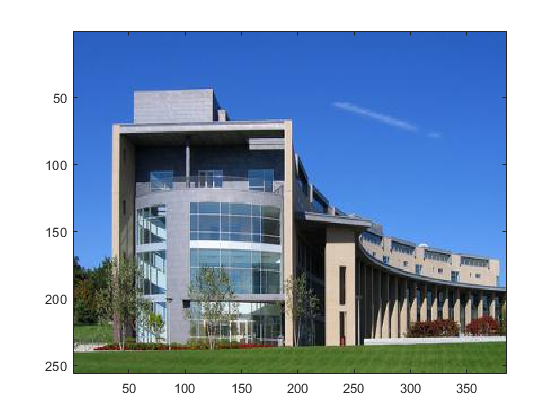

% 2
colormap('gray')

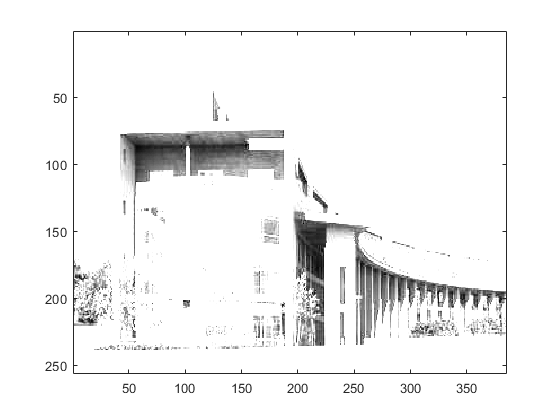

OGray = rgb2gray(O);
image(OGray) % let's see what the grayscale looks like using imshow

Part 3

% 
% find the height and width and apply reshape
height = size(OGray,1);
width = size(OGray,2);
OGrayCol = reshape(OGray, width*height, 1);

Part 4.

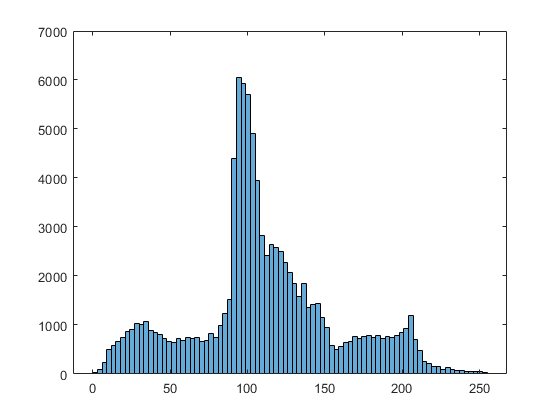

% plot the histogram and find min and max
histogram(OGrayCol)

min(OGrayCol)

ans = uint8
0

max(OGrayCol) 

ans = uint8
255

Yes, it does range from 0 -> 255

Part 5

OGrayCol = double(OGrayCol); % convert to double precision
mu = mean(OGrayCol) % find mean 

mu = 110.1481

sigma = std(OGrayCol) % find standard deviation

sigma = 46.7563

The mean for this image is 110.15, which is close to the middle of the range

Standard deviation is 46.8, which means there are about 2.5-3 standard deviations on either side of the mean, available in the range. 

The intensity does span the range quite well. But it may be better if it is darkened. After playing around with different scalings, I settled on 0.3

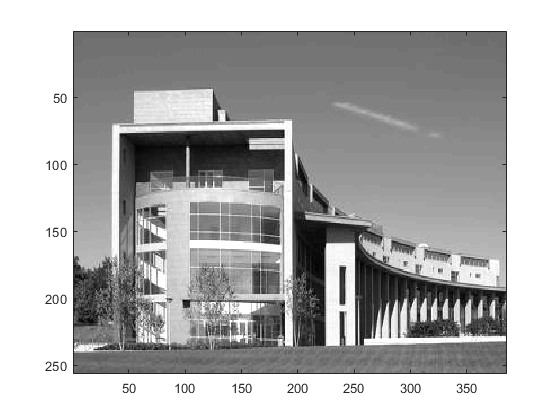

image(OGray*0.3)

Part 6

Most of the data in this graph lives between 10 and 220 (this is just an estimate based on the histogram). However, we note that the picture looks quite washed out. So we can focus on the range 50 - 150, which is where the largest "bump" in the histogram roughly is, and approximately +- 1 standard deviation about the mean . So we may wish to scale our image as follows

y = 255/100*(x-50);

to limit the range to be between 0 and 255

y = max(0, y);

y = min(255, y);

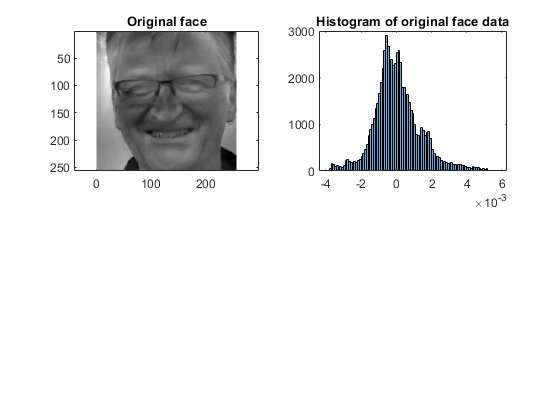

load face_bases
JG = test_images(:,:,230);
subplot(221)
imagesc(JG);
title('Original face')
axis equal
axis equal
JGCol = reshape(JG, 256*256,1);
subplot(222)
histogram(JG)
title('Histogram of original face data')

Observe that the face histogram is centered around 0, and most of the data is in the range -1.5e-3 and 1.5e-3. Note that the standard deviation is 1.3e-3, so this is approximately +- 1 standard deviation around the mean. Please note that this number is subjective. E.g. you may choose to use +-1.3e-3 as your range, or you may use +-2.5e-3. The former will result in more contrast and the latter less contrast. 

So we can make a function that maps our +-1.5e-3 range to 0 -> 255

y = 255/3e-3*(x+1.5e-3)

After testing a few different brightness levels, I settled on a brightness factor of 0.4

In MATLAB, we need to operate on each pixel individually

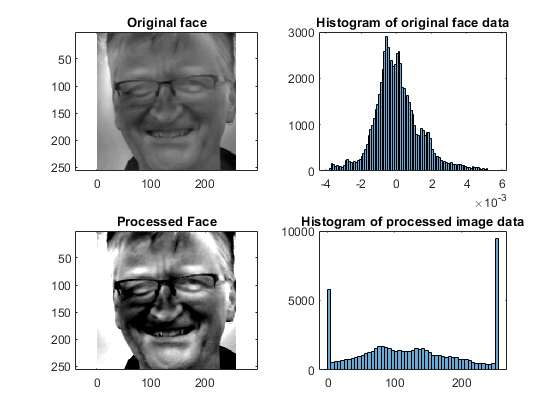

BrightnessFactor = 0.4;
% call the function on each value of the image
JGColScaled = zeros(size(JGCol)); % create some space to store the output data
for k = 1:length(JGCol)
    x = JGCol(k); % pick the k-th element of the vectorized image
    y = 255/(3e-3)*(x+1.5e-3); % scale values
    y = max(y, 0);  % limit the range
    y = min(y, 255);
    JGColScaled(k) = y;
end
JGScaled = reshape(JGColScaled, 256, 256);
subplot(223)
axis equal
imagesc(JGScaled*BrightnessFactor)
axis equal
title('Processed Face')
subplot(224)
histogram(JGColScaled)
title('Histogram of processed image data')

Note that the second image has obviously more contrast and the histogram is more spread out. The pixels occupy more of the range of the image. However, we get many pixels that are saturated at the high and low ends of the range, leading to the large spikes in thehistogram on both ends of the range.